clc
clear all
x1_0 = 1; x2_0 = 0.5;
k1 = 0.0000001; k2 = 0.0000001; k3 = 28.29;
I1 = 0.000364; I2 = 0.000576;
b1 = 3.05; b2 = 8.88; b3 = 0.000001;

x1_0 = 0.5; x2_0 = 0.5;
k1 = 0.1; k2 = 0.1; k3 = 0.1;
I1 = 2; I2 = 2;
b1 = 0.1; b2 = 0.1; b3 = 0.1;


Block_diagrmam

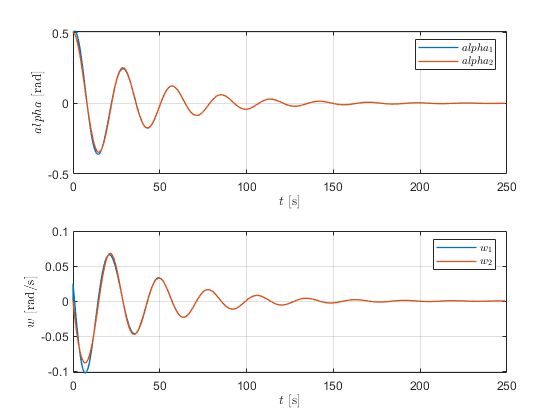

%Lab1_block_diagram
simbd= sim('Lab1_block_diagram');

figure;
subplot(2,1,1)
plot(simbd.logsout{4}.Values.time, simbd.logsout{4}.Values.data,'linewidth',1)
hold on 
plot(simbd.logsout{5}.Values.time, simbd.logsout{5}.Values.data,'linewidth',1)
xlabel('$t$ [s]','interpreter','latex');
ylabel('$alpha$ [rad]','interpreter','latex');
legend('$alpha_1$', '$alpha_2$', 'interpreter','latex')
grid on;
subplot(2,1,2)
plot(simbd.logsout{2}.Values.time, simbd.logsout{2}.Values.data, 'linewidth',1)
hold on
plot(simbd.logsout{3}.Values.time, simbd.logsout{3}.Values.data, 'linewidth',1)
xlabel('$t$ [s]','interpreter','latex');
ylabel('$w$ [rad/s]', 'interpreter','latex');
legend('$w_1$', '$w_2$', 'interpreter','latex')
grid on;

Simscape

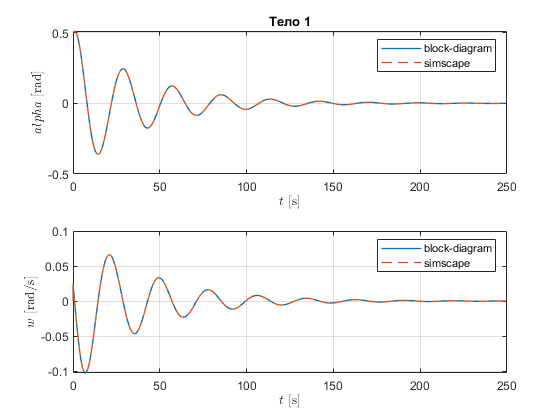

%Lab1_simscape
simSIM = sim('Lab1_simscape');

figure;
subplot(2,1,1)
plot(simbd.logsout{4}.Values.time, simbd.logsout{4}.Values.data,'linewidth',1)
hold on
plot(simSIM.logsout{4}.Values.time, simSIM.logsout{4}.Values.data,'linewidth',1,"LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$alpha$ [rad]','interpreter','latex');
legend('block-diagram', 'simscape')
grid on;
title('Тело 1')
subplot(2,1,2)
plot(simbd.logsout{2}.Values.time, simbd.logsout{2}.Values.data,'linewidth',1)
hold on
plot(simSIM.logsout{3}.Values.time, simSIM.logsout{3}.Values.data,'linewidth',1,"LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$w$ [rad/s]', 'interpreter','latex');
legend('block-diagram', 'simscape')
grid on;

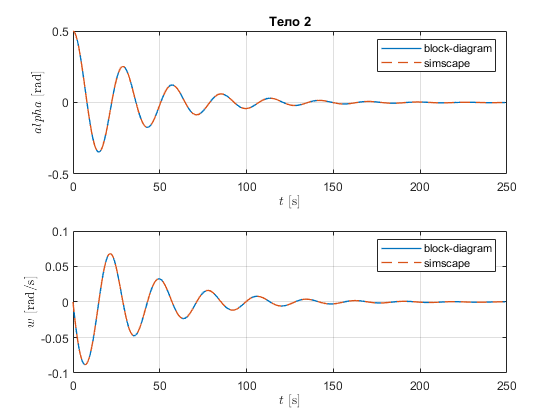



figure;
subplot(2,1,1)
plot(simbd.logsout{5}.Values.time, simbd.logsout{5}.Values.data,'linewidth',1)
hold on
plot(simSIM.logsout{6}.Values.time, simSIM.logsout{6}.Values.data,'linewidth',1,"LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$alpha$ [rad]','interpreter','latex');
legend('block-diagram', 'simscape')
grid on;
title('Тело 2')
subplot(2,1,2)
plot(simbd.logsout{3}.Values.time, simbd.logsout{3}.Values.data,'linewidth',1)
hold on
plot(simSIM.logsout{5}.Values.time, simSIM.logsout{5}.Values.data,'linewidth',1,"LineStyle","--")
xlabel('$t$ [s]','interpreter','latex');
ylabel('$w$ [rad/s]', 'interpreter','latex');
legend('block-diagram', 'simscape')
grid on;